# Complex HVAC system 

***with dehumidification and a PLC-unit using component-based modelling with the hybrid dmss class.***

You can find a brief description of the modelling approaches in [1].

[Open Live Script in Matlab](matlab:open('AirConditioningSystemDemo.mlx')) 

clear, close all

In the following sections the different submodels will be build. Some of them in an seperate scripts. You can find the scripts in the demo-directory.

## System description

The following figure shows an overview of the system.

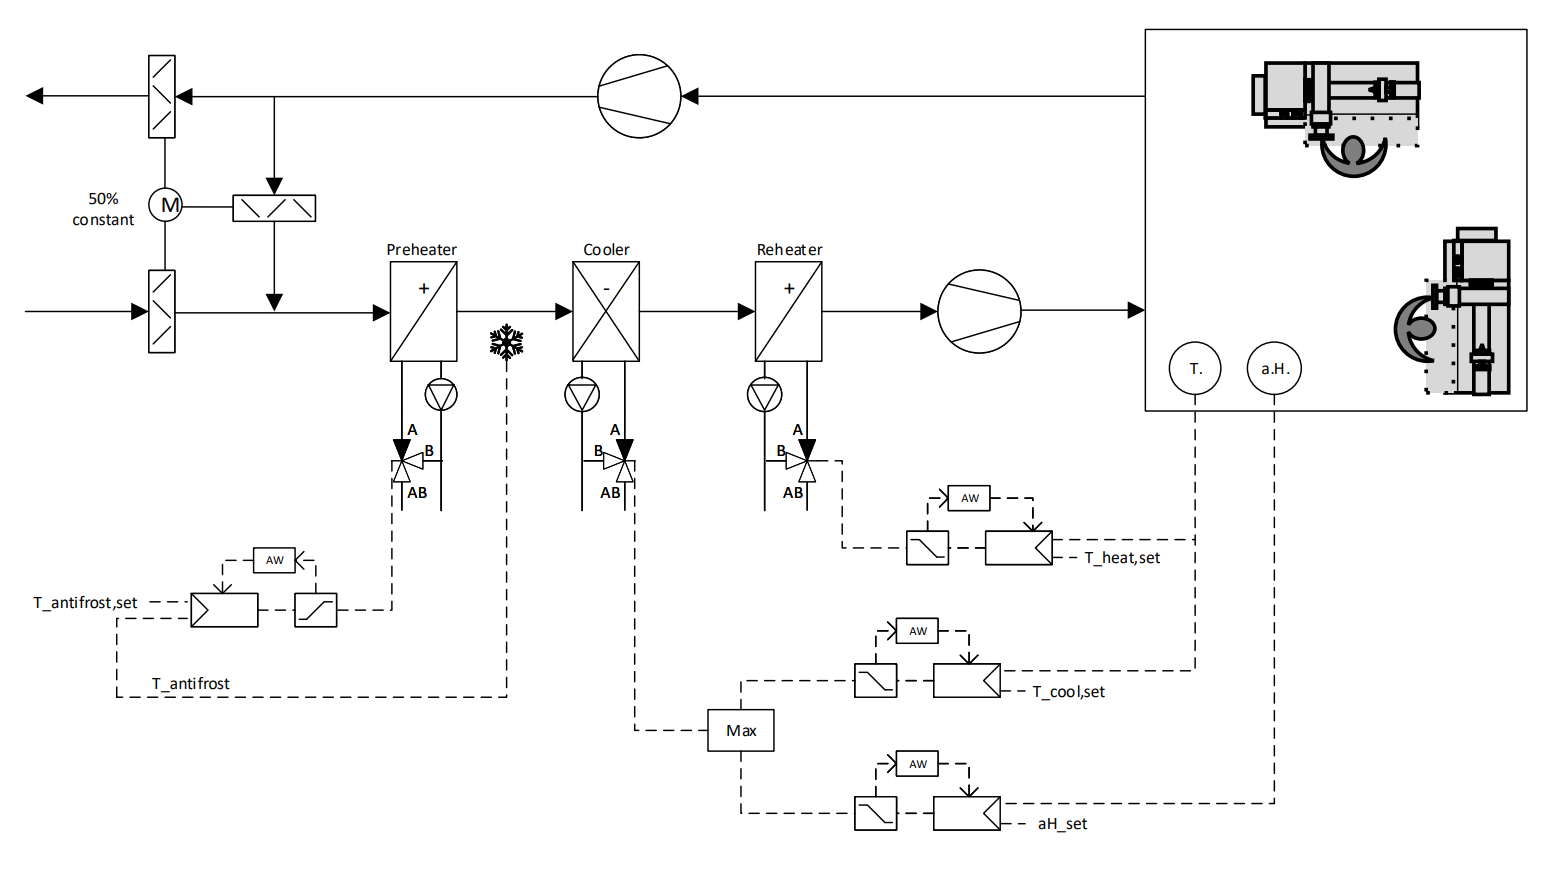

**Figure 1: Illustration of a partial air conditioning plant with an control system supplying a production space.**

Air conditioning systems are widely used to condition the air in supply spaces, e.g. in offices, laboratories or production spaces, and supply fresh air. They are designed and controlled individually for their operation parameters and boundary conditions. 

Here a CAV (constant air volume) partial air conditioning plant with a control system, consisting of PI-controllers and some simple PLC routine, will act to demonstrate the hybrid iMTI modeling approach. The air conditioning system consists of a mixing chamber, where half of the extracted air flow is mixed with outdoor air for maintaining a minimal fresh air supply while still recovering heat from the exhaust air. This is only possible in configurations where the extracted air is not contaminated. 

The mixed air is fed into the preheater which ensures that a minimal air temperature is reached, so that especially the cooler does not freeze. Different from the other heat exchanger configurations, the heating water inlet is on the air inlet side (cross/cocurrent flow), to ensure that also the preheater does not freeze. The temperature of the heating water inlet is controlled by a mixing valve, where the outlet water is mixed with feed water from the heat supply. The mixing valve itself is controlled by a saturated PI-controller with an anti-windup feedback, so that the integral part of the controller is not further increasing when the control signal is saturated. 

The preheater is followed by the air cooler which controls the temperature in cooling operation mode, as well as limiting the absolute humidity of the supply space. The cooler is fed by cooling water in a cross/counter fow configuration. The temperature of the cooling water inlet is controlled by a mixing valve. The set point of the mixing valve is determined by the maximum value of a saturated PI-controller (with anti-windup) for controlling the temperature of the supply space and a saturated PI-Controller (with anti-windup) for controlling the absolute humidity of the supply space. 

Then the air flows into the reheater which in winter also heats the air in addition to the preheater and in summer reheats the air when the cooler dehumidifies the air by cooling it below the saturation temperature. Similar as the preheater, the reheater is controller with a mixing valve, but in cross/counter flow configuration. The valve position is controlled by another saturated PI-controller (with anti-windup) which also controls the supply space's temperature. Here it is important that the setpoints of the PI-controllers of the heater and cooler have a hysteresis in between them, so that there is no unnecessary cooling and reheating. E.g. the setpoint of the temperature-controller of the air cooler could be 21.5 °C while the setpoint of the temperature-controller of the reheater could be 21 °C. 

Afterwards the air flows through the supply fan which also emits waste heat to the air flow. The air flows into the supply space, while cooling, heating or dehumidifying the room's air, in which waste heat from the production occurs, as well as heating/cooling losses to the environment. The extracted air flows through the exhaust fan emitting additional waste heat to the air flow, after which half of the air flow is recirculated, while the other half is released as exhaust air into the environment.

## Component-based modelling

### Component: Heat exchanger model with dehumidification (4-cell model)

Due to the dehumidification the cooler is seperated into 4 cells as depicted in the following figure.

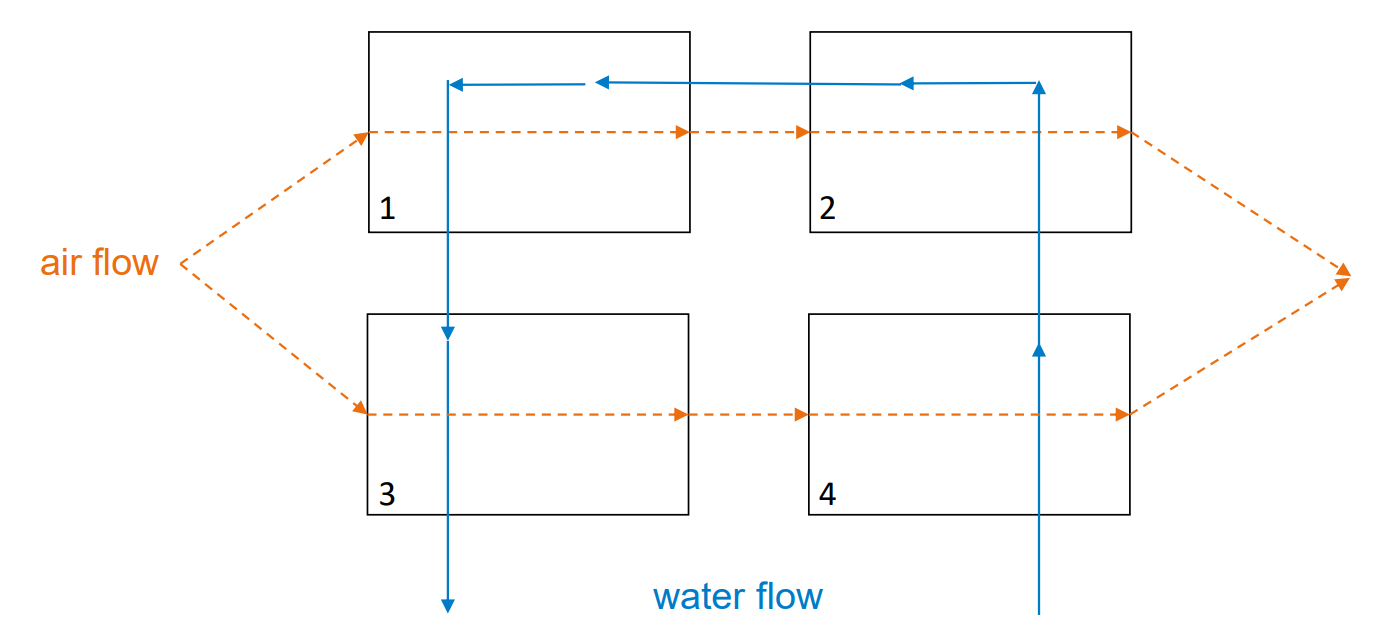

**Figure 2: Illustration of the mass flows in the 4-cell model approach of a water-air heat exchanger.**

This is done, so that partial dehumidification can be modelled. The cell models are generated with the wetHeatExchanger()-script.

sysExchanger = wetHeatExchanger();

Reduced by 4 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 6 column(s) and 0 equation(s) with trivial Reduction due to duplications.


For each cell the input, state and algebraic variable names will be set.

cell1 = sysExchanger;
cell1.stateName = "w13 temperature";
cell1.algebraicName = ["plate 1 temperature", "alpha air 1", "alpha water 1", "a12 temperature", "a12 humidity", "saturated humidity 1"];
cell1.booleanName = "dehumidification 1";
cell1.inputName = ["a01 flow", "water flow", "w21 temperature", "a0 temperature", "a0 humidity"];

cell2 = sysExchanger;
cell2.stateName = "w21 temperature";
cell2.algebraicName = ["plate 2 temperature", "alpha air 2", "alpha water 2", "a20 temperature", "a20 humidity", "saturated humidity 2"];
cell2.booleanName = "dehumidification 2";
cell2.inputName = ["a01 flow", "water flow", "w42 temperature", "a12 temperature", "a12 humidity"];

cell3 = sysExchanger;
cell3.stateName = "w,out temperature";
cell3.algebraicName = ["plate 3 temperature", "alpha air 3", "alpha water 3", "a34 temperature", "a34 humidity", "saturated humidity 3"];
cell3.booleanName = "dehumidification 3";
cell3.inputName = ["a03 flow", "water flow", "w13 temperature", "a0 temperature", "a0 humidity"];

cell4 = sysExchanger;
cell4.stateName = "w42 temperature";
cell4.algebraicName = ["plate 4 temperature", "alpha air 4", "alpha water 4", "a40 temperature", "a40 humidity", "saturated humidity 4"];
cell4.booleanName = "dehumidification 4";
cell4.inputName = ["a03 flow", "water flow", "w,in temperature", "a34 temperature", "a34 humidity"];


Now the cell-models can be connected based of their variable names.

multicellCooler = connect(cell1, cell2, cell3, cell4);

Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 11 column(s) and 0 equation(s) with trivial Reduction due to duplications.


clear cell1 cell2 cell3 cell4

Due to the multicell approach the air flow needs to be split up and mixed up again, before and after the multicell model to calculate the air properties (e.g. temperature) of the mixed air flow. Both models are generate in an external script.

mixingChamberSys = mixingChamber();

Reduced by 3 column(s) and 0 equation(s) with trivial Reduction due to duplications.


mixingChamberSys.algebraicName = ["air flow out", "air temperature out", "air humidity out"];
mixingChamberSys.inputName = ["a01 flow", "a20 temperature", "a20 humidity", "a03 flow", "a40 temperature", "a40 humidity"];

splittingChamberSys = splittingChamber(0.5);

Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.


splittingChamberSys.algebraicName = ["a01 flow", "a03 flow"];
splittingChamberSys.inputName = "air flow";

As before the models will be connect via their variable names with the multicell cooler.

multicellCooler = connect(multicellCooler, mixingChamberSys, splittingChamberSys);

Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 8 column(s) and 0 equation(s) with trivial Reduction due to duplications.


clear mixingChamberSys splittingChamberSys sysExchanger


Some variables will be renamed, because they are the overall output and input of the complete multicell cooler model.

multicellCooler.stateName(3) = "cooler water outlet temperature"

multicellCooler =   dmss with properties:

                          H: [1×1 hyCPN1]
                          n: 4
                          m: 5
                          p: 29
                          q: 4
                outputIndex: [1×1 struct]
                        nEq: 33
                      nIneq: 4
                  stateName: ["w13 temperature"    "w21 temperature"    "cooler water outlet temperature"    "w42 temperature"]
                  stateUnit: [""    ""    ""    ""]
              algebraicName: ["plate 1 temperature"    "alpha air 1"    "alpha water 1"    "a12 temperature"    "a12 humidity"    "saturated humidity 1"    "plate 2 temperature"    "alpha air 2"    "alpha water 2"    …    ] (1×29 string)
              algebraicUnit: [""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""]
 

multicellCooler.inputName = ["cooler water flow", "preheater air outlet temperature", "mixed air humidity", "cooler water inlet temperature", "air flow"];
multicellCooler.algebraicName(25:27) = ["cooler air flow", "cooler air outlet temperature", "cooler air outlet humidity"];

### Component: Heat exchanger model for heating (1-cell)

The reheater and preheater are modelled simply by a 1-cell approach with unified properties and states. The heater models are generated in the external heater()-script. Their signals will be named as well to connect them later to the other components.

reheater = heater(40000);

Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 4 column(s) and 0 equation(s) with trivial Reduction due to duplications.


reheater.stateName = "reheater water outlet temperature";
reheater.inputName = ["air flow", "reheater water flow", "reheater water inlet temperature", "cooler air outlet temperature", "cooler air outlet humidity"];
reheater.algebraicName = ["reheater plate temperature", "reheater convective heattransfer coefficient air", "reheater convective heattransfer coefficient water", "reheater air outlet temperature"];

preheater = heater(10000);

Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 4 column(s) and 0 equation(s) with trivial Reduction due to duplications.


preheater.stateName = "preheater water outlet temperature";
preheater.inputName = ["air flow", "preheater water flow", "preheater water inlet temperature", "mixed air temperature", "mixed air humidity"];
preheater.algebraicName = ["preheater plate temperature", "preheater convective heattransfer coefficient air", "preheater convective heattransfer coefficient water", "preheater air outlet temperature"];


### Component: Mixing Chamber (constant mixing of 50% recirculating and 50% outdoor air)

Here the mixing chamber of the HVAC system is modelled, mixing partly recirculating with outdoor air for energy recovery (heat recovery in winter, cooling recovery in summer). The model is generated using the sym2dmss()-function which converts symbolic sets of equations into a dmss model.

rho = 1.204; %kg/m³
cpd = 1006; %J/kgK
cpv = 1860; %J/kgK
h0 = 2501*10^3; %J/kg

eq = ["0 = y2 - 0.5*u2 - 0.5*u4";...
        "0 = (cpd*y1+cpv*y1*y2+h0*y2) - 0.5*(cpd*u1+cpv*u1*u2+h0*u2) - 0.5*(cpd*u3+cpv*u3*u4+h0*u4)"];
mixingChamber = sym2dmss(eq, 0);

Reduced by 3 column(s) and 0 equation(s) with trivial Reduction due to duplications.


mixingChamber = mixingChamber.replaceSymbolicParameters(["cpd", "cpv", "h0"], [cpd, cpv, h0]);
mixingChamber.algebraicName = ["mixed air temperature", "mixed air humidity"];
mixingChamber.inputName = ["extract air temperature", "room humidity", "outdoor air temperature", "outdoor air humidity"];

### Component: Supply space 

The supply space is modelled by seperate sub-models, for the room air, heat and mass transfer due to the ventilation/air conditioning and the inertia of the walls and floor. As before the sym2dmss()-function is used for generation of dmss objects and the sub models are connected via their variable names.

Vr = 9.03*11.33*3.4; %m³
mr = Vr * rho; %kg

Awall = 2*(9.03+11.33)*3.4 + 9.03*11.33; %m²
Afloor = 9.03*11.33; %m²

cwall = 650; %J/kgK
cfloor = 900; %J/kgK
rho_wall = 80; %kg/m³
rho_floor = 2400; %kg/m³
mwall = 0.04 * Awall * rho_wall; %kg
mfloor = 0.3 * Afloor * rho_floor;

k_in = 3; %W/m²K;
k_out = 3; %W/m²K;
lambda_floor = 2; %W/mK
s_floor = 1; %m
k_floor_out = 1 / (s_floor/lambda_floor); %W/m²K

eq = ["0 = m_r*xp1 - u1 - u2 - u3 - u4";...
    "0 = m_r*xp2 - u5 - u6";...
    "0 = c_d*y1 - x1 + h_0*x2 + c_v*x2*y1"];

room = sym2dmss(eq, 0);
room.inputName = ["heattransfer ventilation", "heattransfer wall", "heattransfer floor", "heat source", "humiditytransfer ventilation", "humidity source"];
room.algebraicName = "room temperature";
room.stateName = ["room enthalpy", "room humidity"];
room = room.replaceSymbolicParameters(["m_r", "c_d", "c_v", "h_0"], [mr, cpd, cpv, h0]);

eq = ["0 = c_d*u3*u4 - c_d*u1*u3 - y1 - h_0*u2*u3 + h_0*u3*u5 - c_v*u1*u2*u3 + c_v*u3*u4*u5";...
    "0 = u3*u5 - u2*u3 - y2"];
ventilationinlet = sym2dmss(eq, 0);

Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.


ventilationinlet.inputName = ["room temperature", "room humidity", "air flow", "supply air temperature", "cooler air outlet humidity"];
ventilationinlet.algebraicName = ["heattransfer ventilation", "humiditytransfer ventilation"];
ventilationinlet.stateName = [];
ventilationinlet = ventilationinlet.replaceSymbolicParameters(["c_d", "c_v", "h_0"], [cpd, cpv, h0]);

eq = ["0 = A_wall*k_wallin*u1-A_wall*(k_wallin + k_wallout)*x1 + A_wall*k_wallout*u2-c_wall*m_wall*xp1";...
    "0=A_wall*k_wallin*x1-A_wall*k_wallin*u1-y1"];
walls = sym2dmss(eq, 0);

Reduced by 3 column(s) and 0 equation(s) with trivial Reduction due to duplications.


walls.inputName = ["room temperature", "ambient temperature"];
walls.algebraicName = "heattransfer wall";
walls.stateName = "wall temperature";
walls = walls.replaceSymbolicParameters(["A_wall", "k_wallin", "k_wallout", "m_wall", "c_wall"], [Awall, k_in, k_out, mwall, cwall]);

eq = ["0 = A_floor*k_floorin*u1-A_floor*(k_floorin + k_floorout)*x1 + A_floor*k_floorout*u2-c_floor*m_floor*xp1";...
    "0=A_floor*k_floorin*x1-A_floor*k_floorin*u1-y1"];
floor = sym2dmss(eq, 0);

Reduced by 3 column(s) and 0 equation(s) with trivial Reduction due to duplications.


floor.stateName = "floor temperature";
floor.inputName = ["room temperature", "ground temperature"];
floor.algebraicName = "heattransfer floor";
floor = floor.replaceSymbolicParameters(["A_floor", "k_floorin", "k_floorout", "m_floor", "c_floor"], [Afloor, k_floor_out, k_floor_out, mfloor, cfloor]);

roomSys = connect(room, ventilationinlet, walls, floor);

Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 6 column(s) and 0 equation(s) with trivial Reduction due to duplications.


### Component: Fan waste heat

The electrical power of the fans is mostly converted into heat energy and the air flows temperature is increasing.

supplyFan = sym2dmss("0 = u4*(cpd+cpv*u3)*(y1-u2) - u1", 0);
supplyFan = supplyFan.replaceSymbolicParameters(["cpd", "cpv"], [cpd, cpv]);
supplyFan.inputName = ["supply fan waste heat", "reheater air outlet temperature", "cooler air outlet humidity", "air flow"];
supplyFan.algebraicName = "supply air temperature";

extractFan = sym2dmss("0 = u4*(cpd+cpv*u3)*(y1-u2) - u1", 0);
extractFan = extractFan.replaceSymbolicParameters(["cpd", "cpv"], [cpd, cpv]);
extractFan.inputName = ["extract fan waste heat", "room temperature", "room humidity", "air flow"];
extractFan.algebraicName = "extract air temperature";


### Component: Valves

Here mixing valves are used as indicated in figure 1. The valve openings are modelled as inert linear valves. Additionally the outlet (mixing) temperature has been modelled.

eq = ["0 = u1 - x1 - T_valve*xp1";...
    "0 = u3 - y1 + u2*x1 - u3*x1"];
preheaterValve = sym2dmss(eq, 0);
preheaterValve = preheaterValve.replaceSymbolicParameters("T_valve", 5);
preheaterValve.inputName = ["preheater valve setpoint", "heating water feed temperature", "preheater water outlet temperature"];
preheaterValve.algebraicName = "preheater water inlet temperature";
preheaterValve.stateName = "preheater valve opening";

eq = ["0 = u1 - x1 - T_valve*xp1";...
    "0 = u3 - y1 + u2*x1 - u3*x1"];
reheaterValve = sym2dmss(eq, 0);
reheaterValve = reheaterValve.replaceSymbolicParameters("T_valve", 5);
reheaterValve.inputName = ["reheater valve setpoint", "heating water feed temperature", "reheater water outlet temperature"];
reheaterValve.algebraicName = "reheater water inlet temperature";
reheaterValve.stateName = "reheater valve opening";

eq = ["0 = u1 - x1 - T_valve*xp1";...
    "0 = u3 - y1 + u2*x1 - u3*x1"];
coolerValve = sym2dmss(eq, 0);
coolerValve = coolerValve.replaceSymbolicParameters("T_valve", 5);
coolerValve.inputName = ["cooler valve setpoint", "cooling water feed temperature", "cooler water outlet temperature"];
coolerValve.algebraicName = "cooler water inlet temperature";
coolerValve.stateName = "cooler valve opening";


### Component: PLC and PID Controls

The different valves are mainly controlled by different saturated PID-controllers with anti-windup, with different individual set-points.

PID_eq = ["xp1 = (u2-u1 - K_AW*(z1+z2)*(K_P*(u2-u1)+K_I*x1-y1))";...
    "y1 = (1-z1)*(1-z2)*(K_P*(u2-u1)+K_I*x1)+(1-z1)*z2*K_max";...
    "(2*z1-1)*(K_P*(u2-u1)+K_I*x1) <= 0";...
    "(2*z2-1)*(K_max-(K_P*(u2-u1)+K_I*x1)) <= 0"];

K_max = 1;
K_I = -0.005;
K_P = -0.3;
K_AW = 1/K_P;
preheaterPID = sym2dmss(PID_eq, 0);

Reduced by 21 column(s) and 0 equation(s) with trivial Reduction due to duplications.


preheaterPID.stateName = "preheater error integral";
preheaterPID.inputName = ["antifrost temperature set point", "preheater air outlet temperature"];
preheaterPID.algebraicName = "preheater valve setpoint";
preheaterPID.booleanName = ["preheater valve lower saturation", "preheater valve upper saturation"];
preheaterPID = preheaterPID.replaceSymbolicParameters(["K_max", "K_I", "K_P", "K_AW"], [K_max, K_I, K_P, K_AW]);

K_max = 1;
K_I = -0.005;
K_P = -0.3;
K_AW = 1/K_P;
reheaterPID = sym2dmss(PID_eq, 0);

Reduced by 21 column(s) and 0 equation(s) with trivial Reduction due to duplications.


reheaterPID.stateName = "reheater error integral";
reheaterPID.inputName = ["room temperature heating set point", "room temperature"];
reheaterPID.algebraicName = "reheater valve setpoint";
reheaterPID.booleanName = ["reheater valve lower saturation", "reheater valve upper saturation"];
reheaterPID = reheaterPID.replaceSymbolicParameters(["K_max", "K_I", "K_P", "K_AW"], [K_max, K_I, K_P, K_AW]);


The cooling valve is controlled by 2 PID-controllers, where one is controlling the temperature in the cooling case of the supply space, while the other is controlling the humidity which is limited to a maximum value for the supply space. The control output changes based of the maximum value of the 2 PID controllers.

K_max = 1;
K_I = 0.005;
K_P = 0.3;
K_AW = 1/K_P;
coolerTemperaturePID = sym2dmss(PID_eq, 0);

Reduced by 21 column(s) and 0 equation(s) with trivial Reduction due to duplications.


coolerTemperaturePID.stateName = "cooler error integral (temperature controller)";
coolerTemperaturePID.inputName = ["room temperature cooling set point", "room temperature"];
coolerTemperaturePID.algebraicName = "cooler valve setpoint (temperature controller)";
coolerTemperaturePID.booleanName = ["cooler valve lower saturation (temperature controller)", "cooler valve upper saturation (temperature controller)"];
coolerTemperaturePID = coolerTemperaturePID.replaceSymbolicParameters(["K_max", "K_I", "K_P", "K_AW"], [K_max, K_I, K_P, K_AW]);

K_max = 1;
K_I = 5;
K_P = 300;
K_AW = 1/K_P;
coolerHumidityPID = sym2dmss(PID_eq, 0);

Reduced by 21 column(s) and 0 equation(s) with trivial Reduction due to duplications.


coolerHumidityPID.stateName = "cooler error integral (humidity controller)";
coolerHumidityPID.inputName = ["room humidity set point", "room humidity"];
coolerHumidityPID.algebraicName = "cooler valve setpoint (humidity controller)";
coolerHumidityPID.booleanName = ["cooler valve lower saturation (humidity controller)", "cooler valve upper saturation (humidity controller)"];
coolerHumidityPID = coolerHumidityPID.replaceSymbolicParameters(["K_max", "K_I", "K_P", "K_AW"], [K_max, K_I, K_P, K_AW]);

coolerPLCeq = ["(1-z1)*u1 + z1*u2 - y1 = 0";...
                "(2*z1-1) * (u1 - u2) <=0"];
coolerPLC = sym2dmss(coolerPLCeq, 0);

Reduced by 3 column(s) and 0 equation(s) with trivial Reduction due to duplications.


coolerPLC.inputName = ["cooler valve setpoint (temperature controller)", "cooler valve setpoint (humidity controller)"];
coolerPLC.algebraicName = "cooler valve setpoint";
coolerPLC.booleanName = "cooler humidity control activation";
coolerControls = connect(coolerPLC, coolerTemperaturePID, coolerHumidityPID);

Reduced by 3 column(s) and 0 equation(s) with trivial Reduction due to duplications.


### Connecting all components

Based of the signal names all components will be connected.

coolerSys = connect(multicellCooler, coolerValve, coolerControls);

Reduced by 1 column(s) and 0 equation(s) with trivial Reduction due to duplications.


preheaterSys = connect(preheater, preheaterValve, preheaterPID);

Reduced by 1 column(s) and 0 equation(s) with trivial Reduction due to duplications.


reheaterSys = connect(reheater, reheaterValve, reheaterPID);

Reduced by 1 column(s) and 0 equation(s) with trivial Reduction due to duplications.


airConditioning = connect(extractFan, mixingChamber, preheaterSys, coolerSys, reheaterSys, supplyFan);

Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 6 column(s) and 0 equation(s) with trivial Reduction due to duplications.


sys = connect(airConditioning, roomSys);

Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 7 column(s) and 0 equation(s) with trivial Reduction due to duplications.


To enable faster run time of the script, the model data will be saved in a .mat file.

## Simulation

In the following different simulations will be performed. First a winter and summer scenraio of the preivous build model will be computed. 

Afterwards unneccessary algebraic variables and equations will be eliminated to reduce simulation time and results will be shown. 

At the last step discretization for two different timesteps will be shown using the simple euler forward approach, one with an unstable and the other one with a stable result.

But at first the model data will be loaded. (Note: you can run the script from here to the end for faster compilation, since the model build up takes some time)

load('AirConditioningSystem.mat')

### Simulation: Winter scenario

ts = 60;
t = 0:ts:60*60;

opt = odeset('RelTol', 10.0^(-3),'AbsTol',10.0^(-6), 'MaxStep', 60);
opt.InequalityZeroTolerance = 1e-6;
opt.InequalityPositivityTolerance = 1e-6;

rho = 1.204; %kg/m³
cpd = 1006; %J/kgK
cpv = 1860; %J/kgK
h0 = 2501*10^3; %J/kg

x0 = 18*ones(sys.n,1); %21
x0([2, 3, 8, 9, 10, 12, 13]) = 0.1;%0.01;
x0(15) = 0.001;
x0(14) = (cpd+cpv*x0(15))*22 + h0*x0(15);

u = [1500, 7000/3600*rho, -8, 0.001, 0.119, 50, 10, 1.19, 8, 21.5, 0.010, 0.476, 21, 2500, 3000, 0, 21, 8] .* ones(length(t),1);

yguess = [];

tic
result = dmsim(sys, x0, yguess, [], t, u, opt);
toc()

Elapsed time is 63.389578 seconds.


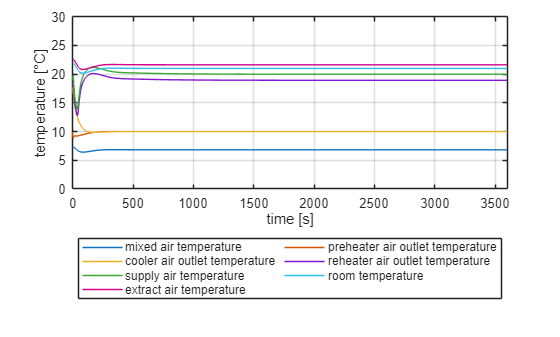

close all

figure()
plot(result.tsim, result.y(:,[2, 7, 35, 46, 49, 50,1]))
xlabel('time [s]')
ylabel('temperature [°C]')
grid on
axis([0 result.tsim(end) 0 30])
legend(result.sys.algebraicName([2, 7, 35, 46, 49, 50,1]),'Location','southoutside', 'Orientation','horizontal', 'NumColumns',2)

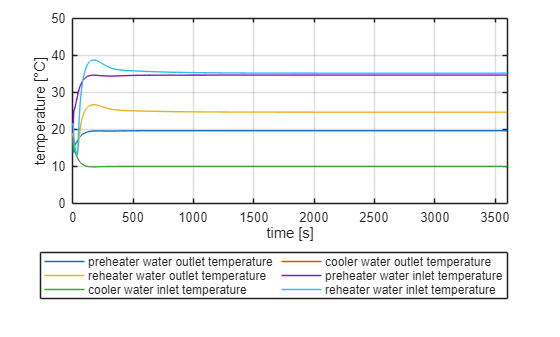


figure()
plot(result.tsim, result.x(:, [1, 6, 11]))
hold on
plot(result.tsim, result.y(:, [8, 39, 47]))
xlabel('time [s]')
ylabel('temperature [°C]')
grid on
axis([0 result.tsim(end) 0 50])
legend([result.sys.stateName([1, 6 , 11]) result.sys.algebraicName([8, 39, 47])],'Location','southoutside', 'Orientation','horizontal', 'NumColumns',2)
hold off

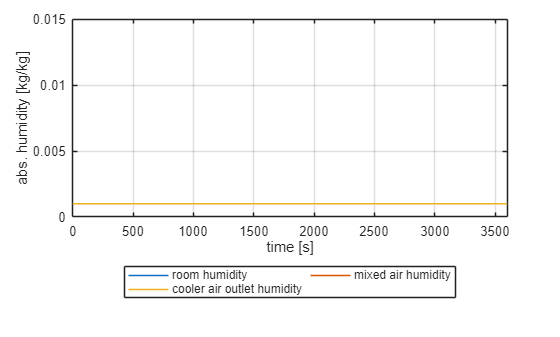


figure()
plot(result.tsim, result.x(:, 15))
hold on
plot(result.tsim, result.y(:, [3, 36]))
xlabel('time [s]')
ylabel('abs. humidity [kg/kg]')
grid on
legend([result.sys.stateName(15), result.sys.algebraicName([3, 36])],'Location','southoutside', 'Orientation','horizontal', 'NumColumns',2)
axis([0 result.tsim(end) 0 0.015])
hold off

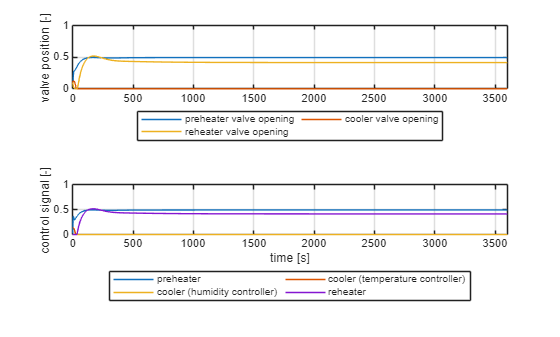


figure()
subplot(2,1,1)
plot(result.tsim, result.x(:,[2, 8, 12]))
ylabel('valve position [-]')
grid on
axis([0 result.tsim(end) 0 1])
legend(result.sys.stateName([2, 8, 12]),'Location','southoutside', 'Orientation','horizontal', 'NumColumns',2)

subplot(2,1,2)
plot(result.tsim, result.y(:,[9, 41,42, 48]))
ylabel('control signal [-]')
xlabel('time [s]')
grid on
axis([0 result.tsim(end) 0 1])
legend(["preheater", "cooler (temperature controller)" , "cooler (humidity controller)", "reheater"],'Location','southoutside', 'Orientation','horizontal', 'NumColumns',2)

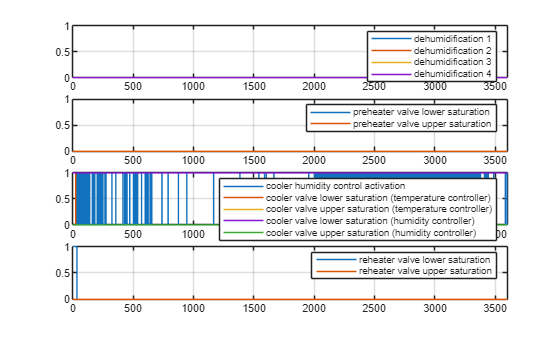


figure()
subplot(4,1,1)
plot(result.zt, result.z(:, 3:6))
grid on
axis([0 result.tsim(end) 0 1])
legend(sys.booleanName(3:6))

subplot(4,1,2)
plot(result.zt, result.z(:, 1:2))
grid on
axis([0 result.tsim(end) 0 1])
legend(sys.booleanName(1:2))

subplot(4,1,3)
plot(result.zt, result.z(:, 7:11))
grid on
axis([0 result.tsim(end) 0 1])
legend(sys.booleanName(7:11))

subplot(4,1,4)
plot(result.zt, result.z(:, 12:13))
grid on
axis([0 result.tsim(end) 0 1])
legend(sys.booleanName(12:13))

### Simulation: Summer scenario

ts = 60;
t = 0:ts:60*60;

opt = odeset('RelTol', 10.0^(-3),'AbsTol',10.0^(-6), 'MaxStep', 60);

x0 = 21*ones(sys.n,1);
x0([2, 3, 8, 9, 10, 12, 13]) = 0.01;
x0(15) = 0.001;
x0(14) = (cpd+cpv*x0(15))*22 + h0*x0(15);

u = [1500, 7000/3600*rho, 35, 0.012, 0.119, 50, 10, 1.19, 8, 21.5, 0.010, 0.476, 21, 2500, 3000, 0, 21, 16] .* ones(length(t),1);

tic
result = dmsim(sys, x0, yguess, [], t, u, opt);
toc()

Elapsed time is 2.554435 seconds.


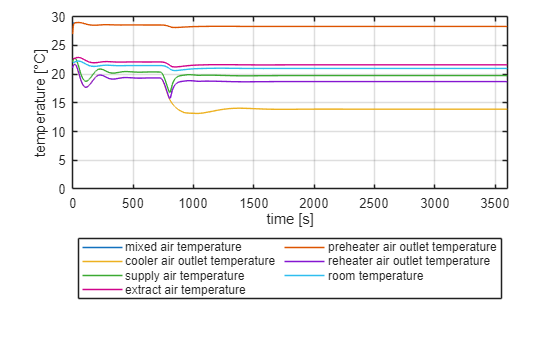

close all

figure()
plot(result.tsim, result.y(:,[2, 7, 35, 46, 49, 50,1]))
xlabel('time [s]')
ylabel('temperature [°C]')
grid on
axis([0 result.tsim(end) 0 30])
legend(result.sys.algebraicName([2, 7, 35, 46, 49, 50,1]),'Location','southoutside', 'Orientation','horizontal', 'NumColumns',2)

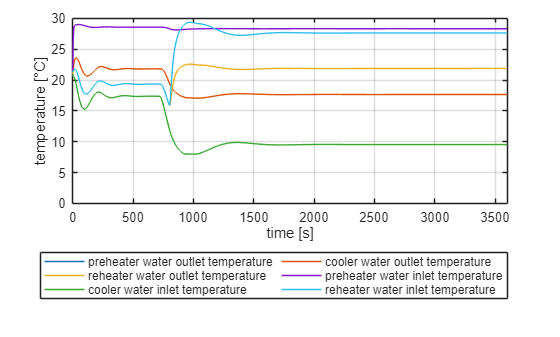


figure()
plot(result.tsim, result.x(:, [1, 6, 11]))
hold on
plot(result.tsim, result.y(:, [8, 39, 47]))
xlabel('time [s]')
ylabel('temperature [°C]')
grid on
axis([0 result.tsim(end) 0 30])
legend([result.sys.stateName([1, 6 , 11]) result.sys.algebraicName([8, 39, 47])],'Location','southoutside', 'Orientation','horizontal', 'NumColumns',2)
hold off

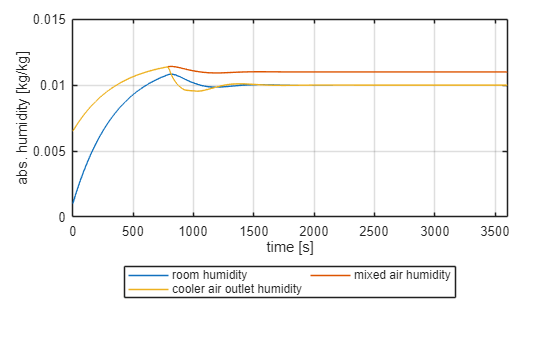


figure()
plot(result.tsim, result.x(:, 15))
hold on
plot(result.tsim, result.y(:, [3, 36]))
xlabel('time [s]')
ylabel('abs. humidity [kg/kg]')
grid on
legend([result.sys.stateName(15), result.sys.algebraicName([3, 36])],'Location','southoutside', 'Orientation','horizontal', 'NumColumns',2)
axis([0 result.tsim(end) 0 0.015])
hold off

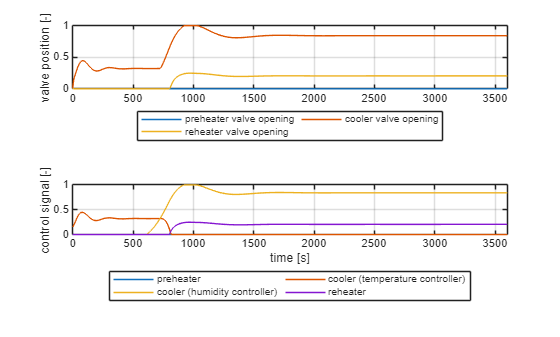


figure()
subplot(2,1,1)
plot(result.tsim, result.x(:,[2, 8, 12]))
ylabel('valve position [-]')
grid on
axis([0 result.tsim(end) 0 1])
legend(result.sys.stateName([2, 8, 12]),'Location','southoutside', 'Orientation','horizontal', 'NumColumns',2)

subplot(2,1,2)
plot(result.tsim, result.y(:,[9, 41,42, 48]))
ylabel('control signal [-]')
xlabel('time [s]')
grid on
axis([0 result.tsim(end) 0 1])
legend(["preheater", "cooler (temperature controller)" , "cooler (humidity controller)", "reheater"],'Location','southoutside', 'Orientation','horizontal', 'NumColumns',2)

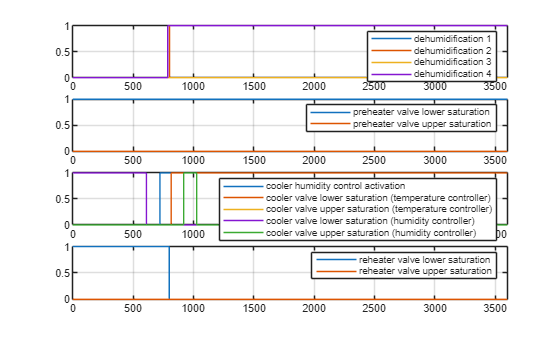


figure()
subplot(4,1,1)
plot(result.zt, result.z(:, 3:6))
grid on
axis([0 result.tsim(end) 0 1])
legend(sys.booleanName(3:6))

subplot(4,1,2)
plot(result.zt, result.z(:, 1:2))
grid on
axis([0 result.tsim(end) 0 1])
legend(sys.booleanName(1:2))

subplot(4,1,3)
plot(result.zt, result.z(:, 7:11))
grid on
axis([0 result.tsim(end) 0 1])
legend(sys.booleanName(7:11))

subplot(4,1,4)
plot(result.zt, result.z(:, 12:13))
grid on
axis([0 result.tsim(end) 0 1])
legend(sys.booleanName(12:13))

### Algebraic Model Reduction

sys_reduced = sys.algebraicElimination([1,2,3,7,35,36,46,49,50]);

System reduced algebraicly by 10 algebraic variable(s) and 10 equation(s).



u = [1500, 7000/3600*rho, 35, 0.012, 0.119, 50, 10, 1.19, 8, 21.5, 0.010, 0.476, 21, 2500, 3000, 0, 21, 16] .* ones(length(t),1);

tic
result_reduced = dmsim(sys_reduced, x0, yguess, [], t, u, opt);
toc()

Elapsed time is 1.888576 seconds.



tic
result = dmsim(sys, x0, yguess, [], t, u, opt);
toc()

Elapsed time is 2.156101 seconds.


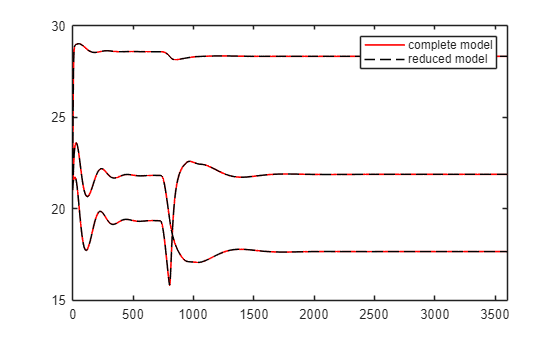


figure()
plot(result.tsim, nan(size(result.tsim)),'r-', LineWidth=1.2)
hold on 
plot(result.tsim, nan(size(result.tsim)),'k--')
plot(result.tsim, result.x(:,[1,6,11]), 'r-', LineWidth=1.2)
plot(result_reduced.tsim, result_reduced.x(:,[1,6,11]),'k--')
axis([0 result.tsim(end) 15 30])
legend(["complete model", "reduced model"])
hold off

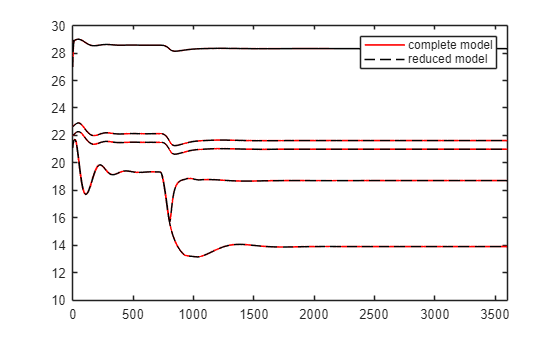


figure()
plot(result.tsim, nan(size(result.tsim)),'r-', LineWidth=1.2)
hold on 
plot(result.tsim, nan(size(result.tsim)),'k--')
plot(result.tsim, result.y(:,[1,2,7,35,46,50]), 'r-', LineWidth=1.2)
plot(result_reduced.tsim, result_reduced.y(:,[1,2,7,34,41,44]),'k--')
axis([0 result.tsim(end) 10 30])
legend(["complete model", "reduced model"])
hold off

### Discrete time simulations using sparsity analysis

For discrete-time simulations algorithm for equation reordering by sparsity pattern analysis and explicit solutions strategies are implemented.

For demonstrative purpose the unsorted sparsity pattern and reordered sparsity pattern will be shown. The algotirhm itself identifies sub-problems and explicit solvable equations based on the reordered sparsity pattern.

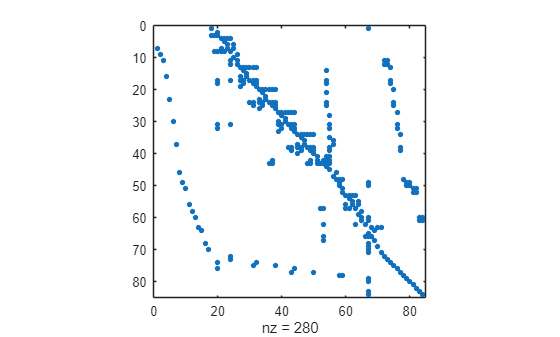

I = incidenceMatrix(sys);
I = [I.equality.stateDerivative, I.equality.algebraic, I.equality.boolean;...
    I.inequality.stateDerivative, I.inequality.algebraic, I.inequality.boolean];
figure()
spy(I)

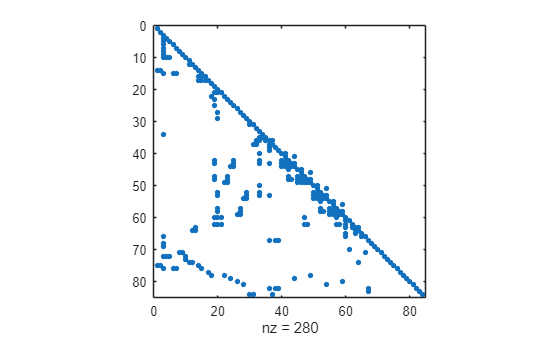

I = sys.orderIncidenceMatrix(I);
figure()
spy(I)

#### Unstable discretization with C2D

ts = 4; %3
t = 0:ts:60*60; %30

sys_d = sys.c2d(ts);

System reduced algebraicly by 17 algebraic variable(s) and 17 equation(s).


sys_d = sys_d.algebraicElimination;

System reduced algebraicly by 10 algebraic variable(s) and 10 equation(s).


u = [1500, 7000/3600*rho, 35, 0.012, 0.119, 50, 10, 1.19, 8, 21.5, 0.010, 0.476, 21, 2500, 3000, 0, 21, 16] .* ones(length(t),1);

tic
result = dmsim(sys_reduced, x0, yguess, [], t, u);
toc()

Elapsed time is 1.863204 seconds.


tic
result_d = dmsim(sys_d, x0, yguess, [], t, u);
toc()

Elapsed time is 24.058194 seconds.


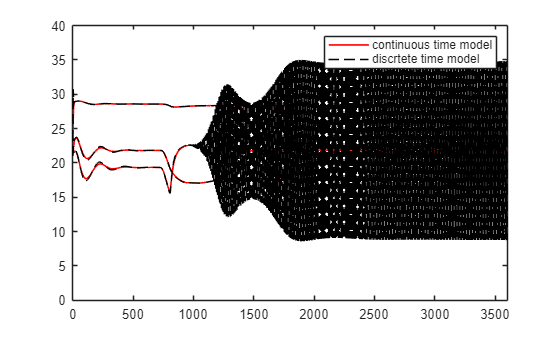

figure()
plot(result_d.tsim, nan(size(result_d.tsim)),'r-', LineWidth=1.2)
hold on 
plot(result_d.tsim, nan(size(result_d.tsim)),'k--')
plot(result.tsim, result.x(:,[1,6,11]), 'r-', LineWidth=1.2)
plot(result_d.tsim, result_d.x(:,[1,6,11]),'k--')
axis([0 result.tsim(end) 0 40])
legend(["continuous time model", "discrtete time model"])
hold off

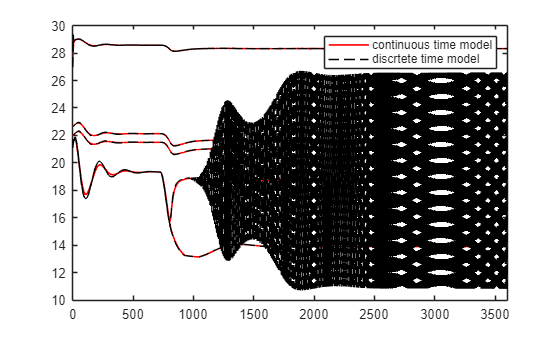


figure()
plot(result.tsim, nan(size(result.tsim)),'r-', LineWidth=1.2)
hold on 
plot(result.tsim, nan(size(result.tsim)),'k--')
plot(result.tsim, result.y(:,[1,2,7,34,41,44]), 'r-', LineWidth=1.2)
plot(result_d.tsim, result_d.y(:,[1,2,7,34,41,44]),'k--')
axis([0 result.tsim(end) 10 30])
legend(["continuous time model", "discrtete time model"])
hold off

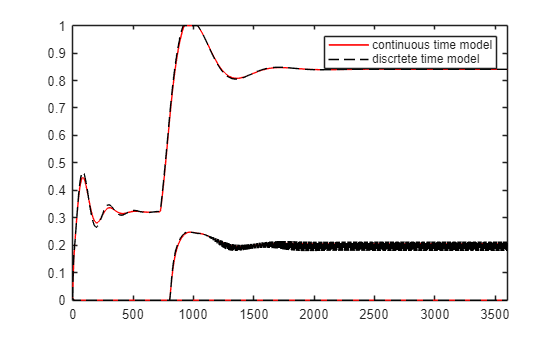

figure()
plot(result.tsim, nan(size(result.tsim)),'r-', LineWidth=1.2)
hold on 
plot(result.tsim, nan(size(result.tsim)),'k--')
plot(result.tsim, result.x(:,[2, 8, 12]), 'r-')
plot(result_d.tsim, result_d.x(:,[2, 8, 12]), 'k--')
axis([0 result.tsim(end) 0 1])
legend(["continuous time model", "discrtete time model"])
hold off

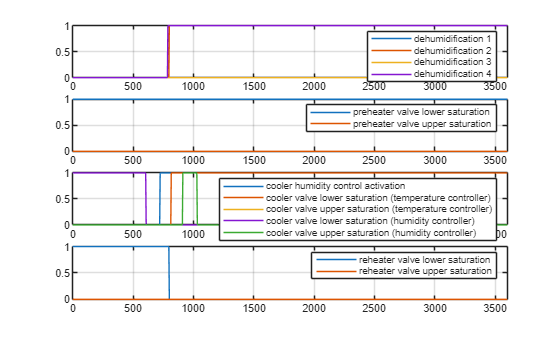

figure()
subplot(4,1,1)
plot(result_d.zt, result_d.z(:, 3:6))
grid on
axis([0 result.tsim(end) 0 1])
legend(sys.booleanName(3:6))

subplot(4,1,2)
plot(result_d.zt, result_d.z(:, 1:2))
grid on
axis([0 result.tsim(end) 0 1])
legend(sys.booleanName(1:2))

subplot(4,1,3)
plot(result_d.zt, result_d.z(:, 7:11))
grid on
axis([0 result_d.tsim(end) 0 1])
legend(sys.booleanName(7:11))

subplot(4,1,4)
plot(result_d.zt, result_d.z(:, 12:13))
grid on
axis([0 result_d.tsim(end) 0 1])
legend(sys.booleanName(12:13))

#### Stable discretization with C2D

ts = 3;
sys_d = sys.c2d(ts);

System reduced algebraicly by 17 algebraic variable(s) and 17 equation(s).


sys_d_red = sys_d.algebraicElimination;

System reduced algebraicly by 10 algebraic variable(s) and 10 equation(s).


t = 0:ts:60*60;
u = [1500, 7000/3600*rho, 35, 0.012, 0.119, 50, 10, 1.19, 8, 21.5, 0.010, 0.476, 21, 2500, 3000, 0, 21, 16] .* ones(length(t),1);

tic
result_d = dmsim(sys_d, x0, yguess, [], t, u);
toc()

Elapsed time is 35.947169 seconds.


tic
result_d_red = dmsim(sys_d_red, x0, yguess, [], t, u);
toc()

Elapsed time is 31.992116 seconds.


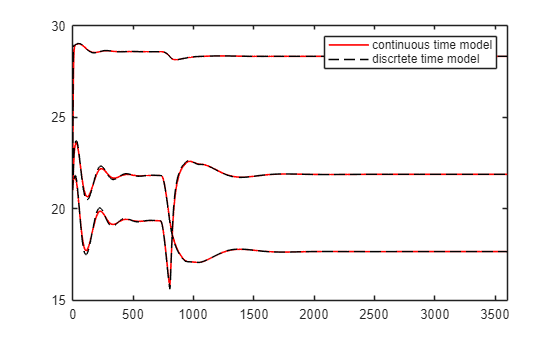


figure()
plot(result_d_red.tsim, nan(size(result_d_red.tsim)),'r-', LineWidth=1.2)
hold on 
plot(result_d_red.tsim, nan(size(result_d_red.tsim)),'k--')
plot(result.tsim, result.x(:,[1,6,11]), 'r-', LineWidth=1.2)
plot(result_d_red.tsim, result_d_red.x(:,[1,6,11]),'k--')
axis([0 result.tsim(end) 15 30])
legend(["continuous time model", "discrtete time model"])
hold off

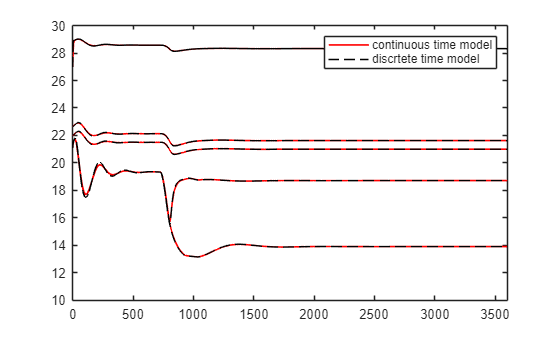


figure()
plot(result_d_red.tsim, nan(size(result_d_red.tsim)),'r-', LineWidth=1.2)
hold on 
plot(result_d_red.tsim, nan(size(result_d_red.tsim)),'k--')
plot(result.tsim, result.y(:,[1,2,7,34,41,44]), 'r-', LineWidth=1.2)
plot(result_d_red.tsim, result_d_red.y(:,[1,2,7,34,41,44]),'k--')
axis([0 result.tsim(end) 10 30])
legend(["continuous time model", "discrtete time model"])
hold off

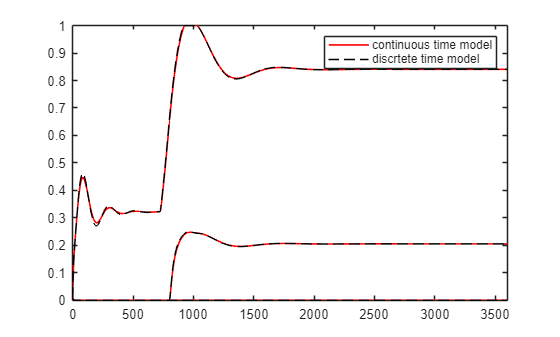

figure()
plot(result_d_red.tsim, nan(size(result_d_red.tsim)),'r-', LineWidth=1.2)
hold on 
plot(result_d_red.tsim, nan(size(result_d_red.tsim)),'k--')
plot(result.tsim, result.x(:,[2, 8, 12]), 'r-', LineWidth=1.2)
plot(result_d_red.tsim, result_d_red.x(:,[2, 8, 12]), 'k--')
axis([0 result_d_red.tsim(end) 0 1])
legend(["continuous time model", "discrtete time model"])
hold off

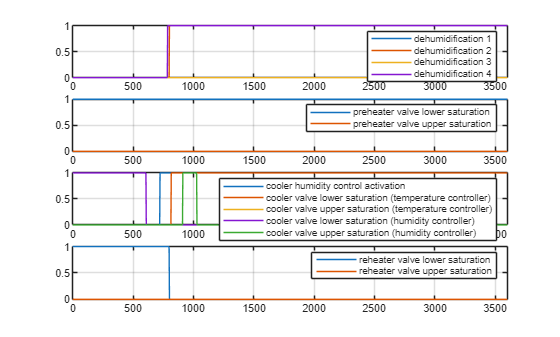


figure()
subplot(4,1,1)
plot(result_d_red.zt, result_d_red.z(:, 3:6))
grid on
axis([0 result_d_red.tsim(end) 0 1])
legend(sys.booleanName(3:6))

subplot(4,1,2)
plot(result_d_red.zt, result_d_red.z(:, 1:2))
grid on
axis([0 result_d_red.tsim(end) 0 1])
legend(sys.booleanName(1:2))

subplot(4,1,3)
plot(result_d_red.zt, result_d_red.z(:, 7:11))
grid on
axis([0 result_d_red.tsim(end) 0 1])
legend(sys.booleanName(7:11))

subplot(4,1,4)
plot(result_d_red.zt, result_d_red.z(:, 12:13))
grid on
axis([0 result_d_red.tsim(end) 0 1])
legend(sys.booleanName(12:13))

## References

[1] T.Warnecke and G. Lichtenberg, "Hybrid implicit multilinear modeling of complex HVAC systems," Simulation and Modeling Methodologies, Technologies and Applications 13th International Conference, SIMULTECH 2023, Springer Nature, 2024. In press.

[2] T. Warnecke and G. Lichtenberg, "Hybrid implicit multilinear simulation using difference algebraic equations reordering by sparsity patterns", 2024 10th International Conference on Control, Decision and Information Technologies (CoDIT), Valletta, Malta, 2024. In press.

Author(s): Torben Warnecke